# 导入电子表格中的数据

用于从以下电子表格导入数据的脚本:

由 MATLAB 于 2021-11-22 00:11:44 自动生成

## 设置导入选项并导入数据

opts = spreadsheetImportOptions("NumVariables", 5);

% 指定工作表和范围
opts.Sheet = "sheet1";
opts.DataRange = "A4:E78255";

% 指定列名称和类型
opts.VariableNames = ["Stkcd", "Trdmnt", "Mretwd", "ritrft", "rMtrft"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% 导入数据
Untitled = readtable("/Users/mac/Desktop/q2 and q4/q2/个股数据.xlsx", opts, "UseExcel", false);

## 转换为输出类型

Untitled = table2array(Untitled)

Untitled = 	1.0e+05 *

    6.0000       NaN    0.0000    0.0000    0.0000
    6.0000       NaN   -0.0000   -0.0000   -0.0000
    6.0000       NaN   -0.0000   -0.0000   -0.0000
    6.0000       NaN   -0.0000   -0.0000   -0.0000
    6.0000       NaN    0.0000    0.0000    0.0000
    6.0000       NaN   -0.0000   -0.0000   -0.0000
    6.0000       NaN   -0.0000   -0.0000    0.0000
    6.0000       NaN    0.0000    0.0000    0.0000
    6.0000       NaN    0.0000    0.0000    0.0000
    6.0000       NaN    0.0000    0.0000   -0.0000


## 清除临时变量

clear opts

## First-pass Regression

i=600000

i = 600000

betaMatrix=[]


betaMatrix =

     []



while i <= 603999;
    for j = Untitled(:);
        a=find(Untitled==i);
        y=Untitled(a,4);
        c=sum(y)/numel(a);
        x=Untitled(a,5);
        b1=x\y;
        betaMatrix=[betaMatrix;i c b1];
    end
    i=i+1;
end

# 导入电子表格中的数据

用于从以下电子表格导入数据的脚本:

由 MATLAB 于 2021-11-22 18:31:00 自动生成

## 设置导入选项并导入数据

opts = spreadsheetImportOptions("NumVariables", 2);

% 指定工作表和范围
opts.Sheet = "Sheet1";
opts.DataRange = "A1:B1454";

% 指定列名称和类型
opts.VariableNames = ["VarName1", "VarName2"];
opts.VariableTypes = ["double", "double"];

% 导入数据
SecondpassRegression = readtable("/Users/mac/Desktop/q2 and q4/q2/Second-pass Regression.xlsx", opts, "UseExcel", false);

## 转换为输出类型

SecondpassRegression = table2array(SecondpassRegression)

SecondpassRegression =     0.6846    0.0089
    0.9405    0.0141
    1.0978    0.0118
    0.7841    0.0107
    0.7292    0.0050
    1.1785    0.0157
    0.7284    0.0222
    0.9998   -0.0007
    1.0017    0.0072
    1.1278    0.0147


## 清除临时变量

clear opts

## Second-pass Regression

Y=SecondpassRegression(:,1)

Y =     0.6846
    0.9405
    1.0978
    0.7841
    0.7292
    1.1785
    0.7284
    0.9998
    1.0017
    1.1278


X=SecondpassRegression(:,2)

X =     0.0089
    0.0141
    0.0118
    0.0107
    0.0050
    0.0157
    0.0222
   -0.0007
    0.0072
    0.0147


b2=regress(Y,X)

b2 = 4.5478

scatter(X,Y)
Y=b2*X
hold on

x1 =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


y1 =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022


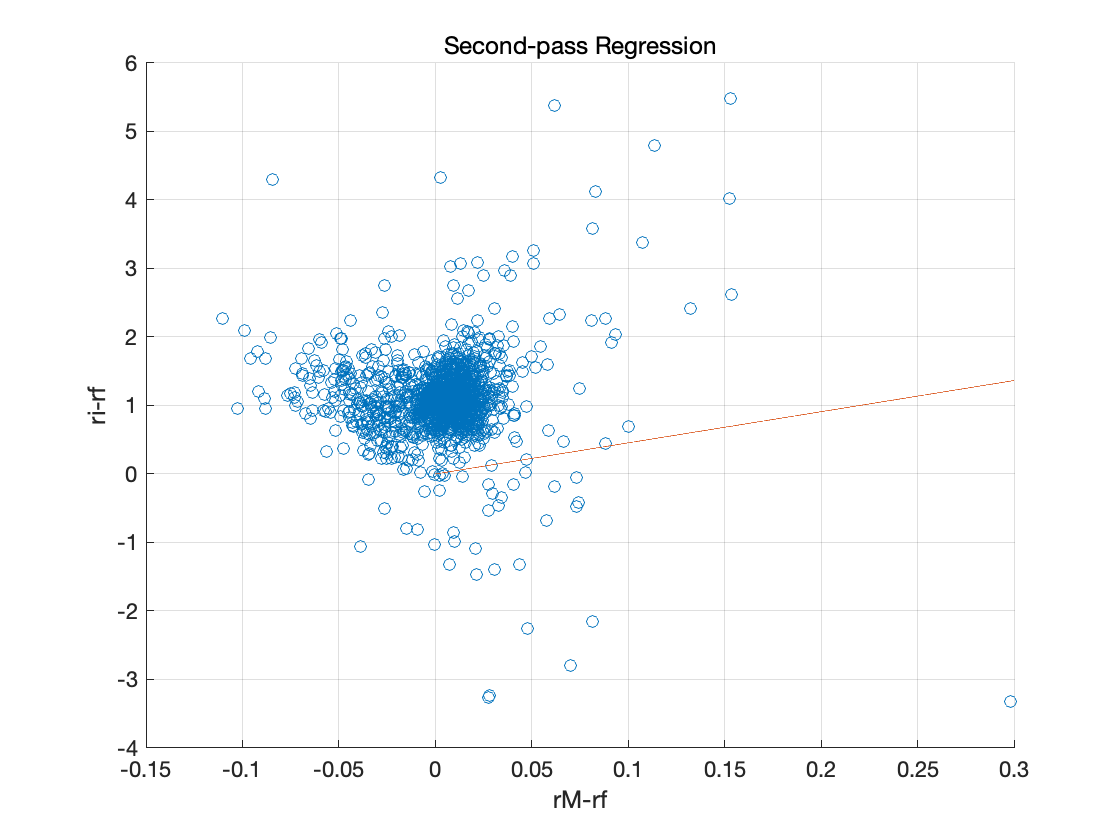

plot(X,Y)
xlabel('rM-rf')
ylabel('ri-rf')
title('Second-pass Regression')
grid on